# Data realizacji ćwiczenia: 1.10.2024r., godz.8.00

# Imię i nazwisko: Szymon Tokarz

Kierunek: Automatyka i Robotyka 

Przedmiot:Sztuczna inteligencja i sensoryka

# Rezultaty:

# Auto-generated by Image Acquisition Explorer

Generated in MATLAB R2023b on 01-Oct-2024 08:45:06

## Connect to Device

Create connection to the device using the specified adaptor with the specified format.

v = videoinput("winvideo", 1, "YUY2_640x360");
%640x360 taka rozdzielczość bo używałęm kamery z laptopa

## Configure Device Properties

Configure videoinput properties to prepare for acquisition.

v.ReturnedColorspace = "rgb";

## Record Video for Set Number of Frames

Record video data for a specified number of frames.

numFrames = 30;
v.FramesPerTrigger = numFrames;

start(v);
wait(v);
stop(v);
recording1 = getdata(v, numFrames);

## Show Recording

View the recorded video.

implay(recording1);

## Clean Up

Delete the videoinput object and clear variables from the workspace.

delete(v)
clear v

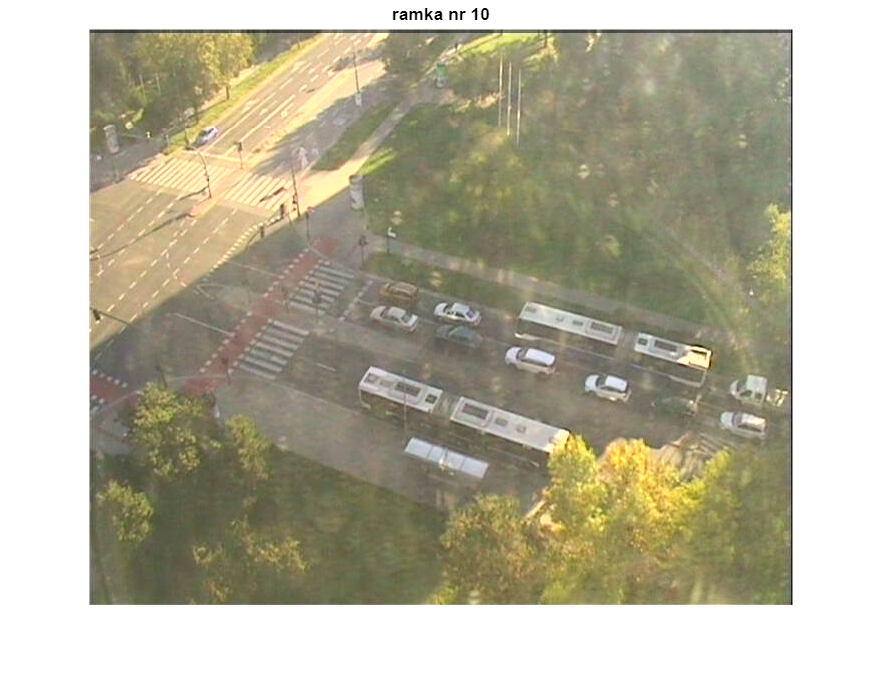

fh = figure;
ile_ramek = 10;
elapsedTime=zeros(1,ile_ramek);
for i = 1:ile_ramek
 tic
 IM = imread('http://149.156.124.49/axis-cgi/jpg/image.cgi');
 elapsedTime(1, i) = toc;

 imshow(IM);
 title(['ramka nr ' num2str(i)])
 drawnow
end

disp(['FPS = ' num2str(1/mean(elapsedTime))])

FPS = 1.2921


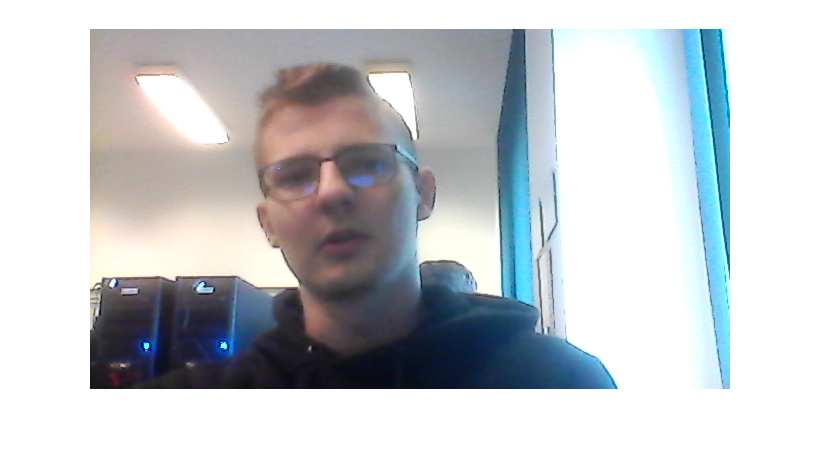

imageViewer(snapshot3)
imshow(snapshot3)



%% Inicjalizacja
camera       = webcam(1);           % ustawic odpowiedni nr kamery

% preview(cam); % podgląd obrazu z kamery
camera.AvailableResolutions

ans = 1×2 cell array
    {'640x480'}    {'640x360'}


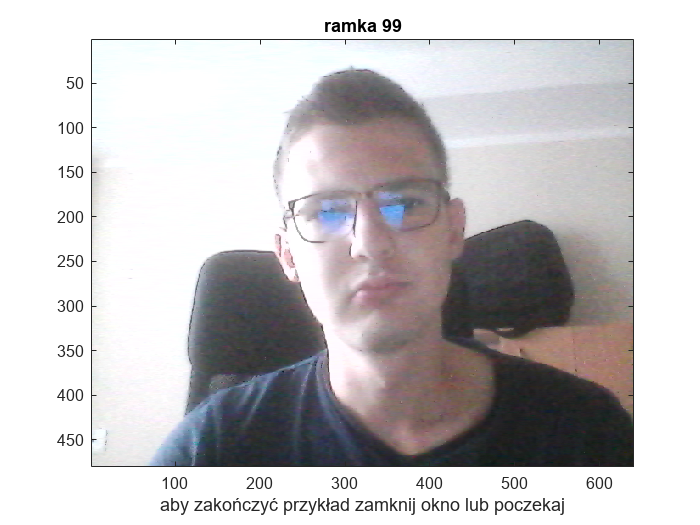


camera.Resolution = '640x480';      % ustawić rozdzielczosć obsługiwaną przez kamerę

%% Akwizycja obrazów
figure

keepRolling = true;
iter =1;
ile_ramek = 100;
set(gcf,'CloseRequestFcn','keepRolling = false; closereq');
elapsedTime=zeros(1,ile_ramek);

while keepRolling & iter<ile_ramek
    tic;
    im = snapshot(camera);
    elapsedTime(1, iter) = toc;
    if ~isempty(im)        
        image(im)              
        title(['ramka ' num2str(iter)]);
        xlabel('aby zakończyć przykład zamknij okno lub poczekaj')
        drawnow
    end
    iter=iter+1;    
end

disp(['FPS = ' num2str(1/mean(elapsedTime))])

FPS = 175.2202


% Usuniecie obiektu kamery 
% (wymagane bo innaczej MATLAB nie zwolni zasobow sprzetowych)
clear camera

close all

frameLength = 1024;         % długość bufora audio w próbkach
fs          = 16000;        % częstotliwość próbkowania w Hz

% obiekt obsługujący wejście audio (mikrofon)
audioReader = audioDeviceReader('SampleRate',fs,...
    'SamplesPerFrame',frameLength);

% obiekt obsługujący wyjście audio (głośnik)
deviceWriter = audioDeviceWriter( ...
    'SampleRate',audioReader.SampleRate);

% obiekt wizualizacji sygnału
scope = dsp.TimeScope( ...
    'SampleRate',audioReader.SampleRate, ...
    'TimeSpan',2, ...
    'BufferLength',audioReader.SampleRate*2*2, ...
    'YLimits',[-1,1], ...
    'TimeSpanOverrunAction',"Scroll");


% obiekt przetwarzania sygnału
reverb = reverberator( ...
    'SampleRate',audioReader.SampleRate, ...
    'PreDelay',0.5, ...
    'WetDryMix',0.4);


%% Pętla akwizycji audio
disp('początek akwizycji audio')

początek akwizycji audio


czasAkwizycji = 25;          % [s]
tic
while toc < czasAkwizycji
    signal = audioReader();
    reverbSignal = reverb(signal);
    deviceWriter(reverbSignal);
    scope([signal,mean(reverbSignal,2)])
end
disp('koniec akwizycji audio')

koniec akwizycji audio


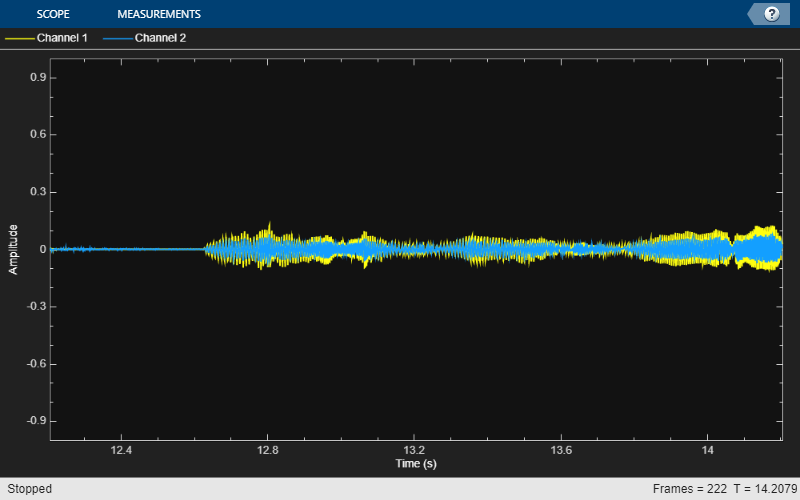


% zwolnienie zasobów
release(audioReader)
release(deviceWriter)
release(reverb)
release(scope)

# Analiza i wnioski:

1) Czas akwizycji jednej ramki to 1/FPS, czyli w tym przypadku 1/30 [s].

Teoretyczny rozmiar tego pliku to rozmiar pojedynczej ramki pomnożony razy ilość ramek, czyli 900. Jedna ramka ma 640x360 pikseli oraz każdy piksel zajmuje 3 B ze względu na RGB. Więc teretyczny romziar wynosi 640*360*3*900=622 080 000 [B].

Rozmiar pliku wynosi 7 500 556[B], więc można zauważyć, że teoretyczna wartość jest mniejsza od rzeczywistej. Wynika to z tego, że rzeczywisty plik zawiera dodatkowe informacje, jak np. tytuł,parametry itd.

2)

 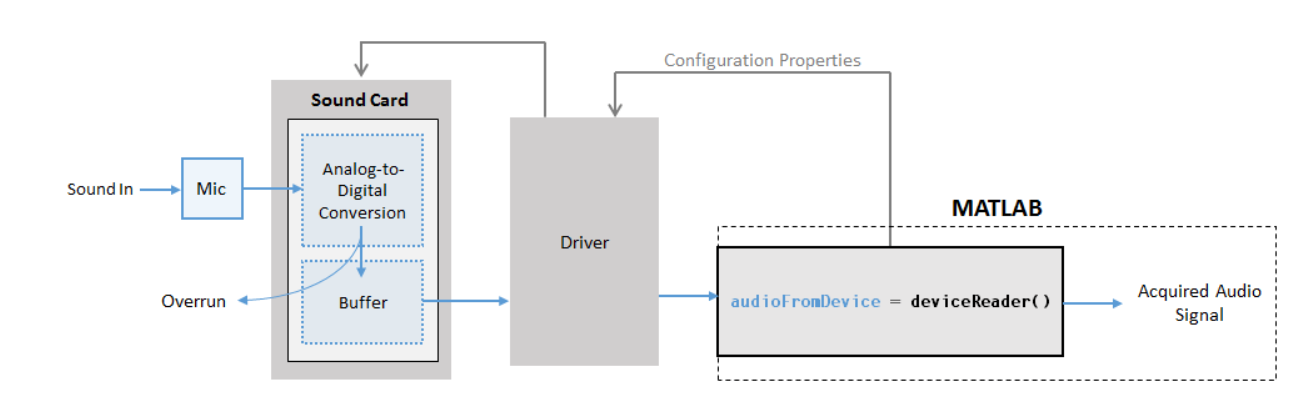

Gdy dane z bufora nie zostaną odczytane, będą utracone ze względu na przepełnienie bufora.

# Pytania

1)Moją uwagę zwróciło to, że image acquisition explorer jest bardzo przyjemnym narzędziem. Można łatwo zmieniać parametry akwizycji oraz przeprowadzać ją w czasie rzeczywistym.

2) Bardzo przydatnymi narzędzami są obiekty tworzone przez Audio i Image Acquisition Toolbox takie jak deviceReader() lub webcam(), ponieważ ułatwiają operację na urządzeniach peryferyjnych komputera i na pewno wykorzystam je w pracy dyplomowej.

3) Czy za pomocą Audio Toolbox można wysłać sygnał przez Bluetooth, a jeżeli nie to czy istnieje jakiś dodatek, który jest łatwy w obsłudze i to robi?